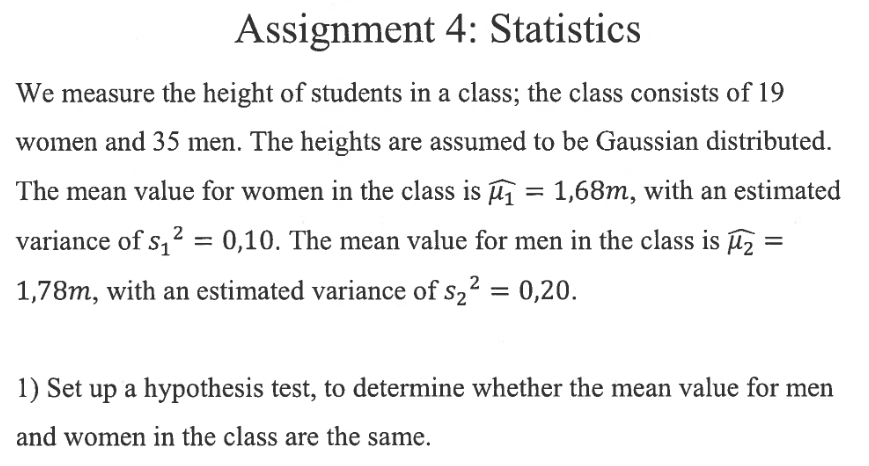

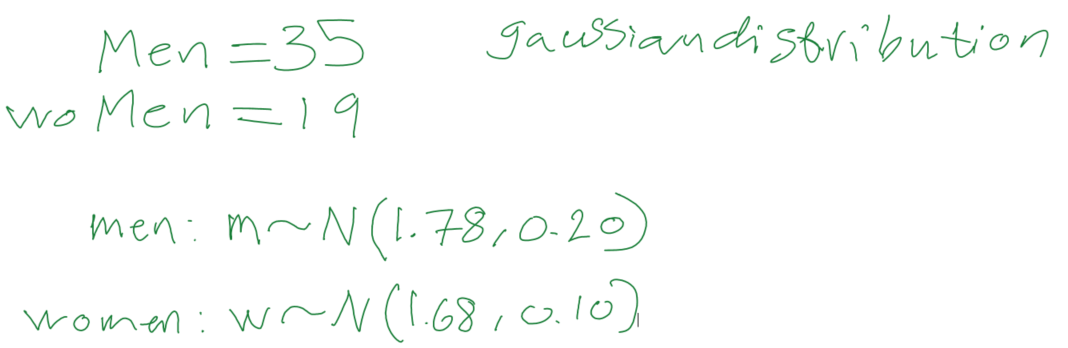

men=35;
women=19;
mu_man = 1.78;
mu_woman = 1.68;
sigma_man = 0.20;
sigma_woman = 0.10;

h0: mu_man = mu_woman

h1 mu_man != mu_woman

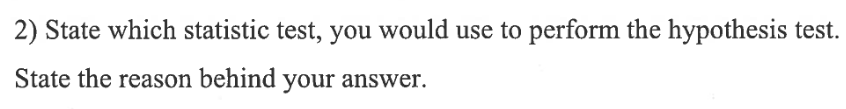

Because the variance is unknown and the data is normally distributted, a t-test will be used on the difference between the means.

mean_diff = abs(mu_man-mu_woman)

mean_diff = 0.1000


standardDeviationDiff = sqrt(((19-1)*0.10+(35-1)*0.20)/(19+35-2))

standardDeviationDiff = 0.4067

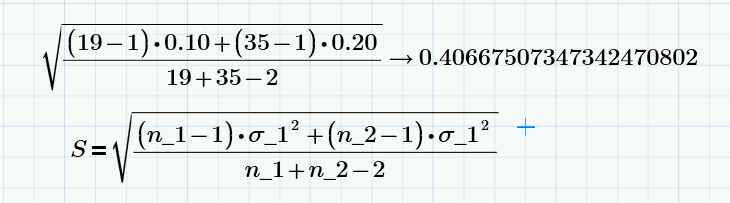

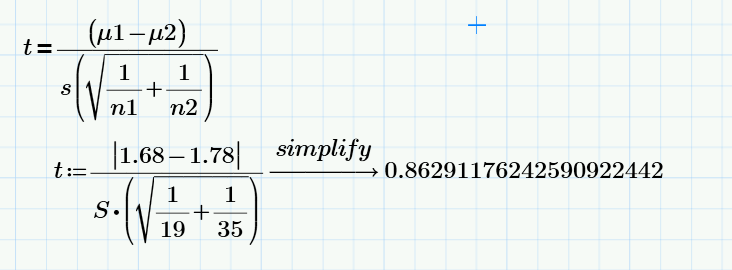


t = mean_diff / (standardDeviationDiff * sqrt(1/women + 1/men))

t = 0.8629

p = 2 * (1 - tcdf(abs(t), women + men -2))

p = 0.3921

P is bigger than 0.05  and the null hypothesis can't be rejected.

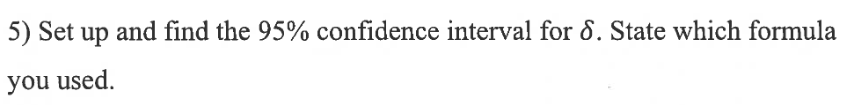

TZero = tinv(0.975, women + men - 2)

TZero = 2.0066

Step = TZero * standardDeviationDiff * sqrt(1/women + 1/men);
min = mean_diff - Step

min = -0.1325

max = mean_diff + Step

max = 0.3325

Interval is therefor [-0.1325,0.3325]